# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.6  带箭头曲线

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

Matlab 提供了一个功能强大的 annotation 函数，可以轻松添加各种标注，箭头就是其中一种；如下效果图，annotation 函数是针对整个 figure 图形，范围限定在 [0, 1] 之间，如果要在指定的真实坐标处绘制箭头，这个方法自然无效了，势必要将真实的坐标转换到 figure 的 [0, 1] 之间。

annotation('arrow', [0, 1], [0, 1]);

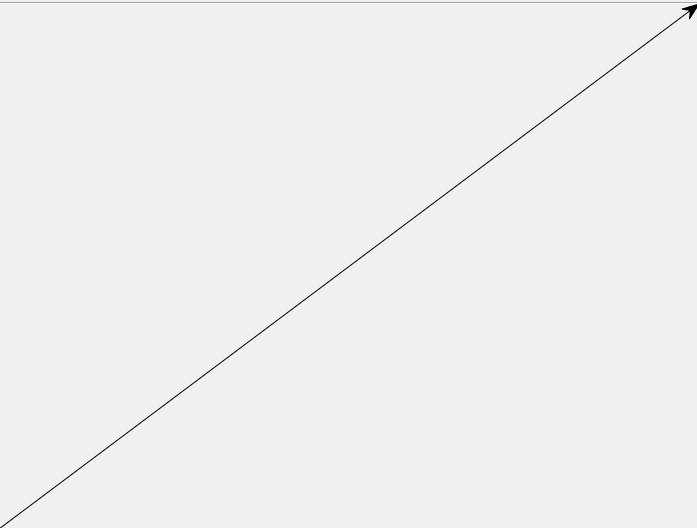

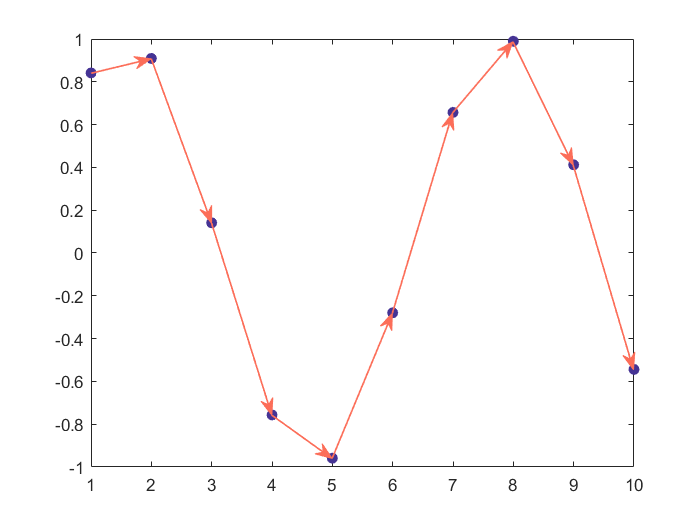

clear; clc;
% 获取到颜色
[all_themes, all_colors] = GetColors();
x = 1:10;
y = sin(x);
plot(x, y, '.');
hold on
for i = 1:9
    PlotLineArrow(gca, [x(i), x(i + 1)], [y(i), y(i + 1)], all_colors(6, :), ...
        all_colors(1, :), 1);
end
hold off